## Read table

T = readtable("ListCapstoneProjects.csv");

T.CapstoneMentor = categorical(T.CapstoneMentor);

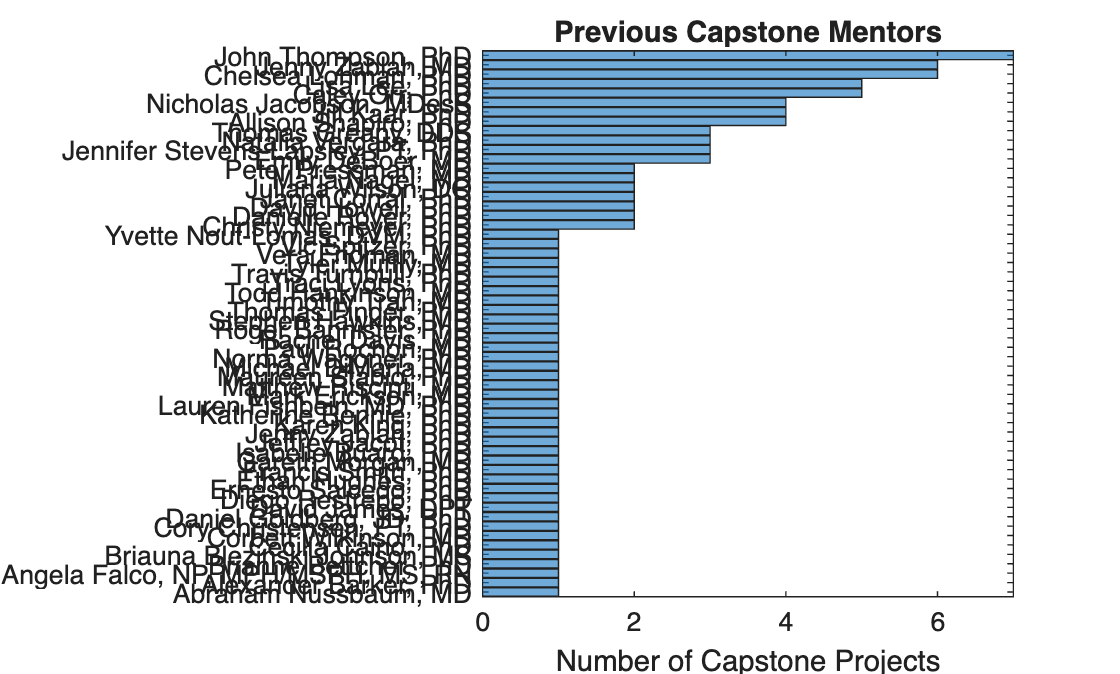

clf;
histogram(T.CapstoneMentor,Orientation='horizontal',DisplayOrder='ascend')
title("Previous Capstone Mentors")
xlabel('Number of Capstone Projects')

textData = string(T.CapstonePresentationTitle);
cleanedData = tokenizedDocument(textData);
cleanedData = addPartOfSpeechDetails(cleanedData);
cleanedData = removeStopWords(cleanedData);
cleanedData = normalizeWords(cleanedData,"Style",'lemma');
cleanedData = erasePunctuation(cleanedData);
cleanedData = removeShortWords(cleanedData,2);
cleanedBag = bagOfWords(cleanedData);
cleanedBag = removeInfrequentWords(cleanedBag,2);
cleanedBag=removeEmptyDocuments(cleanedBag)

cleanedBag =   bagOfWords with properties:

        NumWords: 75
          Counts: [92×75 double]
      Vocabulary: ["lab"    "donor"    "virtual"    "learning"    "subthalamic"    "nucleus"    "patient"    "parkinson"    "disease"    "pulmonary"    "evaluate"    "print"    "protocol"    "anatomical"    "model"    "development"    …    ] (1×75 string)
    NumDocuments: 92


figure;
wordcloud(cleanedBag)